% clear;
fsampu = 2048; % iEMG、sEMG采样率
% level=1;
% trial=2;
% path_eaf=['Z:\Result\24-7-29iEMG-US-sEMG联合采集_陈晨左手\肌电图反解结果\M2L2.5T' num2str(trial) '.eaf'];
% path_iemg=['E:\data\24-7-14iEMG-sEMG联合采集\xEMG_20240714_肱二头肌\xEMG-CC-240714\' ...
%     'CC_iEMG+sEMG-lev' num2str(level) '0_trial' num2str(trial) '.mat'];
% path_semg=['E:\data\24-6-21iEMG-US-sEMG联合采集\signal\iEMG_sEMG后处理\HDsEMG_iEMG_S1_M3_level' num2str(level) '_trial' num2str(trial) '_24-06-21.mat'];
eafdata = importdata("Z:\Result\24-10-12iEMG-sEMG\M2L1T2.eaf"); % 读取eaf文件
% data_i=importdata(path_iemg);
% Data=data_i(1,:);
% data_s=importdata(path_semg);
% clear data_i

提取放电串PT

muNum = max(eafdata.data(:,2)); % MU的个数
iPulses = {};
for mu = 1:muNum
    % iPulses就是这个eaf文件里分解得到的spike train，每个cell表示一个MU，里面的数字是该MU每次放电的时刻
    iPulses{mu} = round(eafdata.data(find(eafdata.data(:,2)==mu),1)'*fsampu); 
end

绘制图像

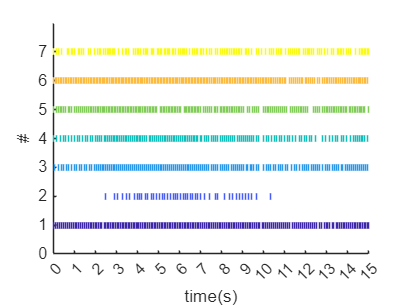

draw_PluseTime(iPulses,fsampu);

得到MUAP

% sigcell=Data;
clf;
[muaps]=muapExtraction(sigcell,iPulses,50,'STA');

绘制原始图像，经过滤波

% plot(Data{1});
band=1000;%高通滤波
[B,A] = butter(4,band/fsampu*2,'high');
Data_filtered=filter(B,A,Data);

函数或变量 'Data' 无法识别。

figure
plot(Data_filtered)

data_i.muaps=muaps;
data_i.Data=Data;
data_i.mupt=iPulses;
data_i.filtdata=Data_filtered;

pulse_semg=data_s.decomps.MUPulses;
for i=1:1:length(pulse_semg)
    Pulses{i}=round(pulse_semg{i}*5);
end
match=PulseMatch(Pulses,iPulses,0.1,10240)

match = 3×10 table
    Pulses1    Pulses2    Sensitivity      RoA       Lag     Sensitivity_CC    FalseAlarm    Precision    Specificity      Acc  
    _______    _______    ___________    ________    ____    ______________    __________    _________    ___________    _______

      19          2         0.11667      0.059211     623       0.089109        0.35664          0.15       0.99967      0.99909
      41          3         0.11712       0.13793    -224        0.23423        0.65306       0.13978         0.999      0.99847
      45          1         0.31461        0.2115     789        0.25281          0.734       0.10922       0.99769      0.99686


match=matchtable{1,2};


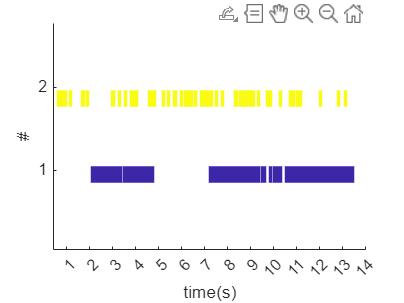

matchidx=1;
clearvars matchpulses
matchpulses{2}=Pulses{match{matchidx,1}};
matchpulses{1}=iPulses{match{matchidx,2}};
draw_PluseTime(matchpulses,10240,1,100,2);

绘制iEMG的MUAP

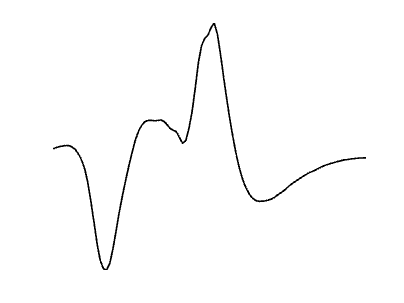

which2show=match{matchidx,2};

figure;clf;plotArrayPotential(muaps{which2show},1,1);

sEMG的MUAP

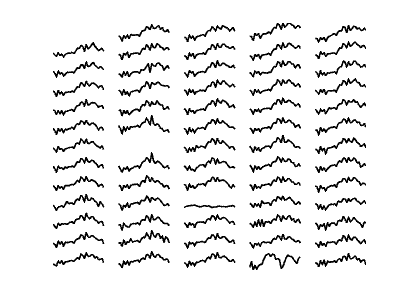

show_semg=match{matchidx,1};
[sigcell]=sig2cell(data_s.data_sEMG,4);
sigcell{7,2}=NaN;
[muaparray,~]=muapExtraction(sigcell,Pulses,30,'STA');

figure;clf;plotArrayPotential(muaparray{show_semg},1,1);

% iemgshow=Data_filtered;
% iemgshow=iemgshow/max(iemgshow);
% clf;
% plot(iemgshow);hold on
% scatter(Pulses{46}',0.2,1e6,'|','r');

%显示峰峰值最大的一个
muapa=muaparray{match{matchidx,1}};

未定义变量 'muaparray'。

p2p=0;largesti=0;largestj=0;
for i=1:13
    for j=1:5
  tmppp=max(muapa{i,j})-min(muapa{i,j});
  if tmppp>p2p
      p2p=tmppp;
        largesti=i;
        largestj=j;
  end
    end
end
clf;
anss{1}=muapa{largesti,largestj};
plotArrayPotential(anss,1,1)


tma=muaps{which2show};
[a,b]=xcorr(tma{1} ,muapa{largesti,largestj})

保存

saveflag=false;
if saveflag
    filename=['match_iEMG_HDsEMG_S1_M3_level' num2str(level) '_trial' num2str(trial) '_24-06-21.mat'];
    save(filename,"match","data_s","data_i");
end